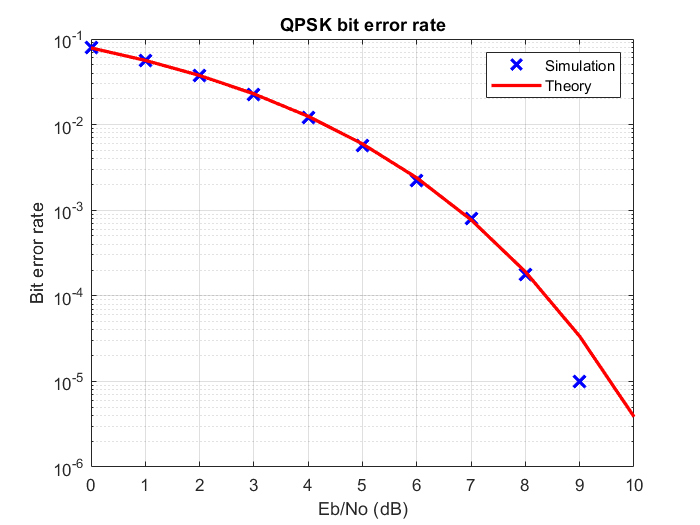

% number of symbols in simulation
Nsyms = 100000;
% energy per symbol
Es = 1;
% energy per bit (2 bits/symbol for QPSK)
Eb = Es / 2;
% Eb/No values to simulate at, in dB
SNRdB = linspace(0, 10, 11);

% Eb/No values in linear scale
SNR = 10.^(SNRdB / 10);
% keep track of bit errors for each Eb/No point
bit_err = zeros(size(SNR));
for i=1:length(SNR)
    % generate source symbols
    syms = (1 - 2 * (randn(Nsyms,1) > 0)) + 1i * (1 - 2 * (randn(Nsyms, 1) > 0));
    % add noise
    syms_noisy = sqrt(Es/2) * syms + sqrt(Eb/(2*SNR(i))) * (randn(size(syms)) + 1i * randn(size(syms)));
    % recover symbols from each component (real and imaginary)
    syms_rec_r = sign(real(syms_noisy));
    syms_rec_i = sign(imag(syms_noisy));
    % count bit errors
    bit_err(i) = sum((syms_rec_r ~= real(syms)) + (syms_rec_i ~= imag(syms)));
end
% convert to bit error rate
bit_err = bit_err / (2 * Nsyms);

% calculate theoretical bit error rate, functionally equivalent to:
% bit_err_theo = qfunc(sqrt(2*EbNo_lin));
bit_err_theo = 0.5*erfc(sqrt(2*SNR)/sqrt(2));
figure;
semilogy(SNRdB, bit_err, 'bx', SNRdB, bit_err_theo, 'r', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('Eb/No (dB)');
ylabel('Bit error rate');
title('QPSK bit error rate');
legend('Simulation','Theory');
grid on;